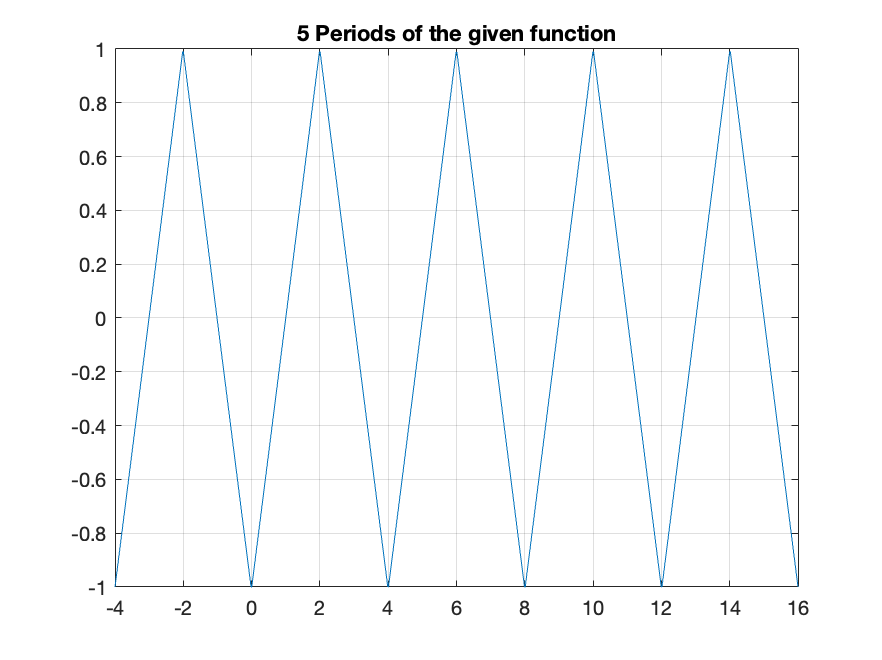

% Group 96 19/12/2021
% Arda Ünver    - 2444081
% Deniz Karakay - 2443307
% Ercihan Kara  - 2375160

% HW2 Q4 Part 1

clc;
clear;

% Period
T = 4;

% "N + 1" period is shown
N = 4;

% 200 samples per one period
samples = 200;

% Given function
f = @(t)(t-1).*(0<=t & t<=2) + (3-t).*(2<=t & t<=4);

% Generating samples in one period
x = linspace(0,T,samples);

% Interval to be shown
intvl = [-T, N*T];

% Copying the original function values to get multiple periods
periodic_fx = repmat(f(x),1,N+1);

% Copying the original input values to get multiple periods
periodic_x = linspace(intvl(1),intvl(2),length(periodic_fx));

% Plot multiple periods
plot(periodic_x, periodic_fx)
grid
title("5 Periods of the given function")

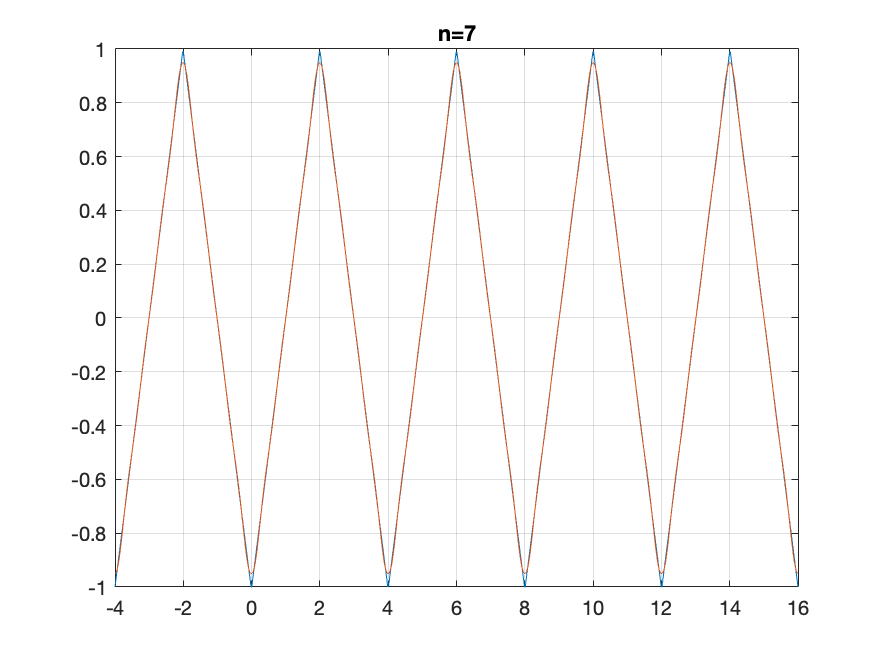


% For k = 7
fs = 7;
sum=0;

% Finding FS coefficients
for k=1:2:fs
    ak=(4)/(k*pi)^2*(-1+(-1)^k); 
    sum=sum+(ak*cos(k*pi*x*1/2));
end 

periodic_sum = repmat(sum,1,N+1);
plot(periodic_x, periodic_fx,periodic_x,periodic_sum)
grid
title('n=7')

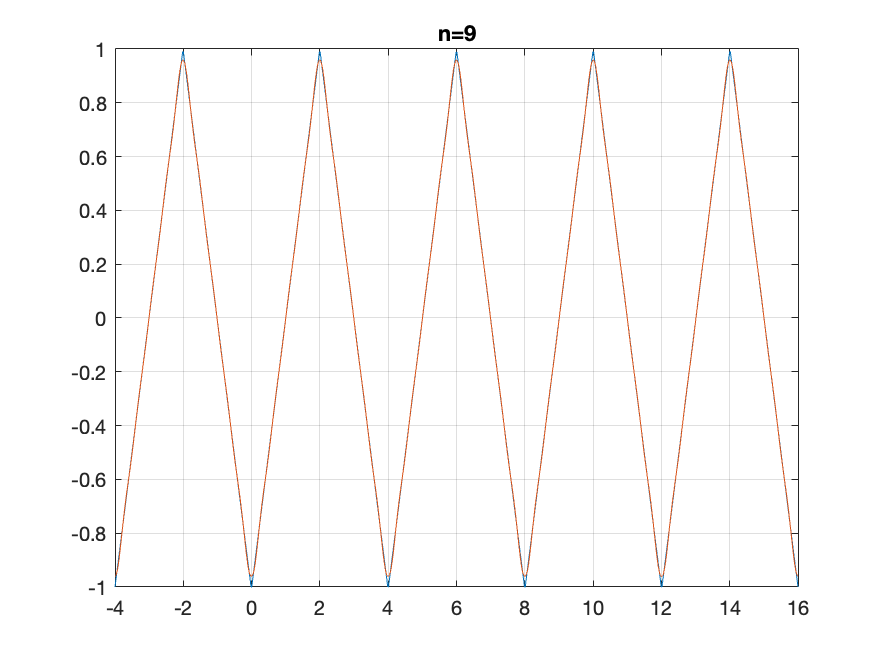



% For k = 9
fs = 9;
sum=0;

% Finding FS coefficients
for k=1:2:fs
    ak=(4)/(k*pi)^2*(-1+(-1)^k); 
    sum=sum+(ak*cos(k*pi*x*1/2));
end 

periodic_sum = repmat(sum,1,N+1);
plot(periodic_x, periodic_fx,periodic_x,periodic_sum)
grid
title('n=9')

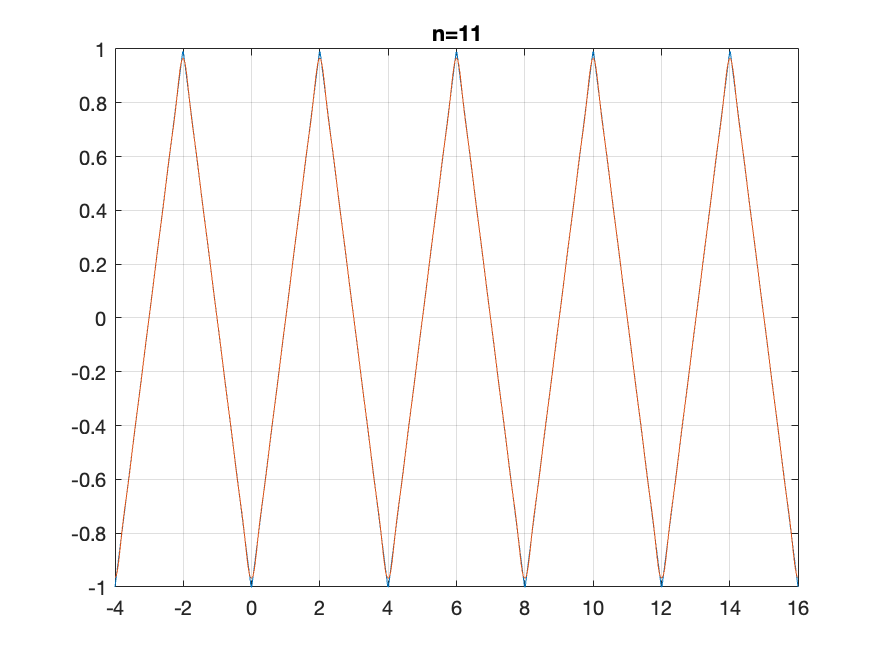



% For k = 11
fs = 11;
sum=0;

% Finding FS coefficients
for k=1:2:fs
    ak=(4)/(k*pi)^2*(-1+(-1)^k); 
    sum=sum+(ak*cos(k*pi*x*1/2));
end 

periodic_sum = repmat(sum,1,N+1);
plot(periodic_x, periodic_fx,periodic_x,periodic_sum)
grid
title('n=11')

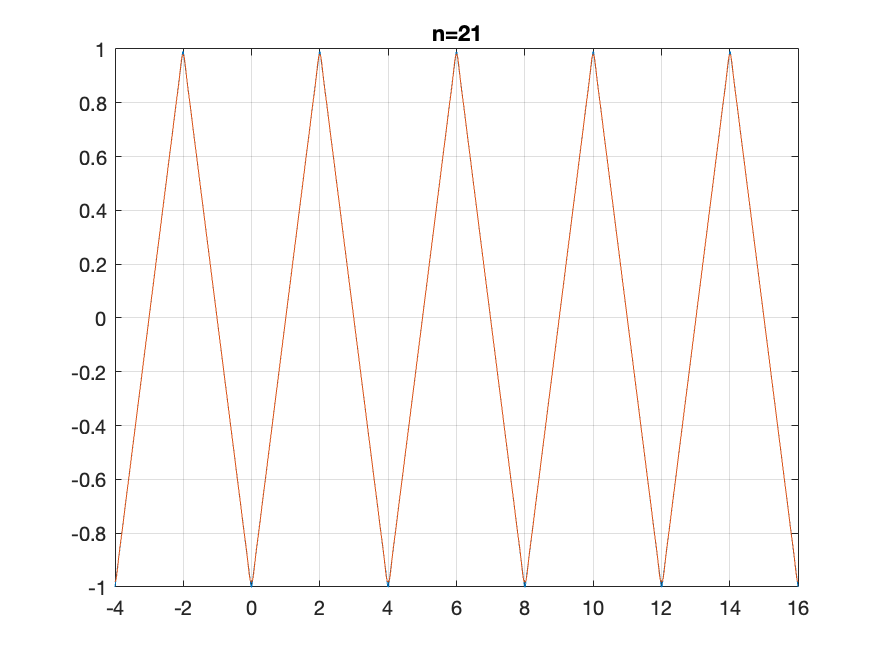


% For k = 21
fs = 21;
sum=0;

% Finding FS coefficients
for k=1:2:fs
    ak=(4)/(k*pi)^2*(-1+(-1)^k); 
    sum=sum+(ak*cos(k*pi*x*1/2));
end 

periodic_sum = repmat(sum,1,N+1);
plot(periodic_x, periodic_fx,periodic_x,periodic_sum)
grid
title('n=21')

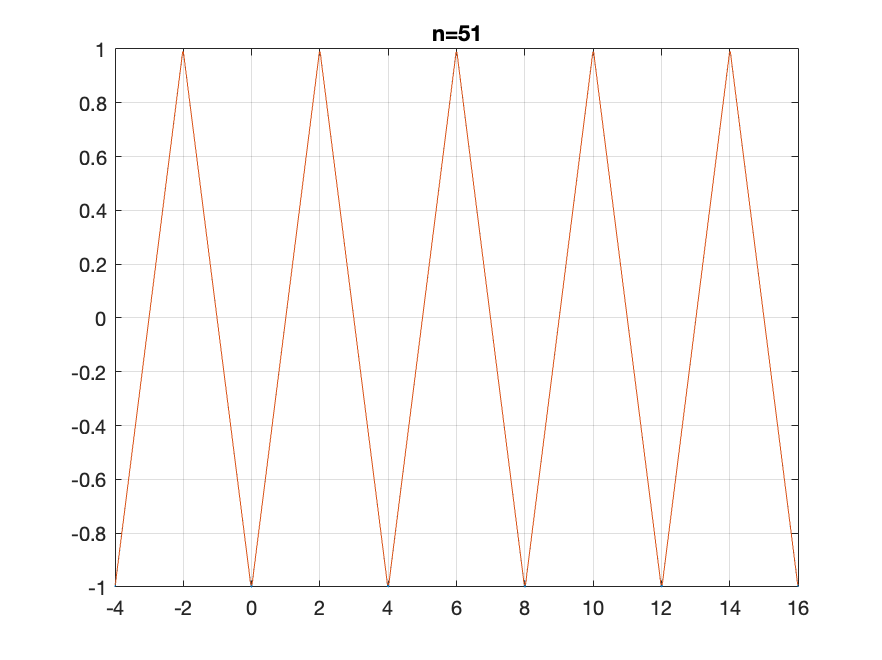



% For k = 51
fs = 51;
sum=0;

% Finding FS coefficients
for k=1:2:fs
    ak=(4)/(k*pi)^2*(-1+(-1)^k); 
    sum=sum+(ak*cos(k*pi*x*1/2));
end 

periodic_sum = repmat(sum,1,N+1);
plot(periodic_x, periodic_fx,periodic_x,periodic_sum)
grid
title('n=51')

% Group 96 19/12/2021
% Arda Ünver    - 2444081
% Deniz Karakay - 2443307
% Ercihan Kara  - 2375160

% HW2 Q4 Part 2


T = 4

T = 4

N = 6

N = 6

delay = 1

delay = 1

samples = 200

samples = 200


f = @(t)(t-1).*(0<=t & t<2) + (3-t).*(2<=t & t<=4);

x = linspace(0,T,samples);

intvl = [-T, (N*T)];
periodic_fx = repmat(f(x),1,N+1);
periodic_x = linspace(intvl(1),intvl(2),length(periodic_fx));

w0 = 2*pi/T;

fs =51

fs = 51

sum=0

sum = 0

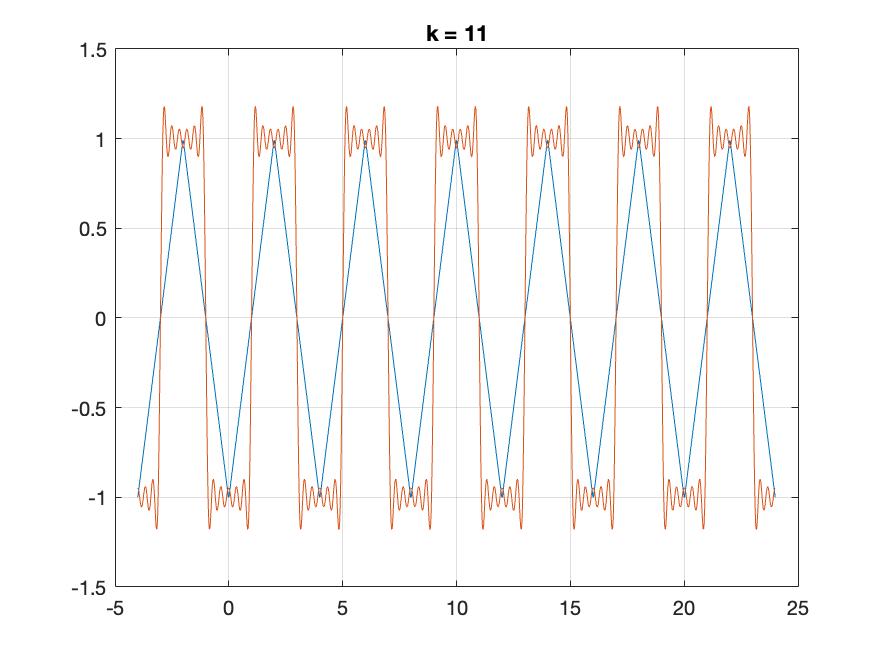

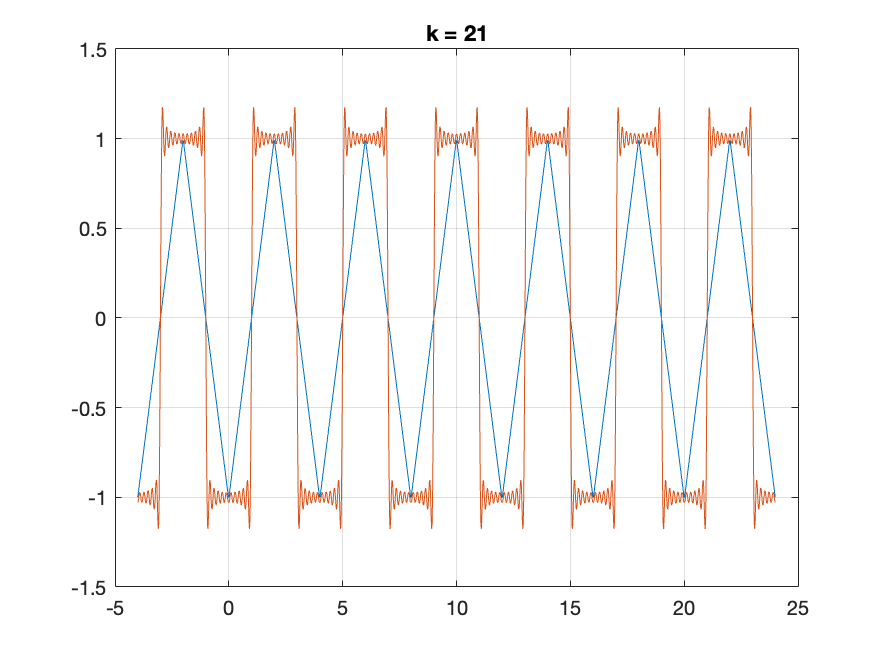

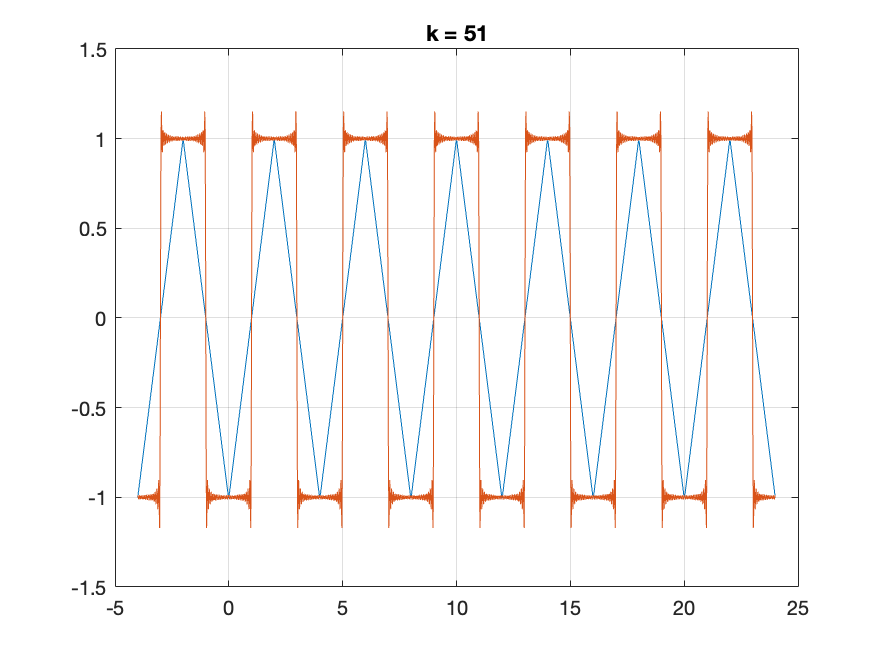

for k=1:2:fs
    ak=(4)/(k*pi)^2*(-1+(-1)^k) * exp(-1j*k*w0) * (1j*k*w0);
    sum=sum+(ak*(cos(k*x*w0)));
    if k == 11
        periodic_sum = repmat(sum,1,N+1);
        plot(periodic_x, periodic_fx,periodic_x,periodic_sum)
        grid
        title('k = 11')
    elseif k == 21
        figure
        periodic_sum = repmat(sum,1,N+1);
        plot(periodic_x, periodic_fx,periodic_x,periodic_sum)
        grid
        title('k = 21')
    elseif k == 51
        figure
        periodic_sum = repmat(sum,1,N+1);
        plot(periodic_x, periodic_fx,periodic_x,periodic_sum)
        grid
        title('k = 51')
    end
end 

clear;

T = 4

T = 4

N = 2

N = 2

samples = 200

samples = 200


f = @(t)(t-1).*(0<=t & t<2) + (3-t).*(2<=t & t<=4);


syms t
y = piecewise(0<=t & t<2,t-1,2<=t & t<=4,3-t);

g = diff(y)

$$g = \left\{ \begin{array}{cl} 1 & \text{ if }t\in \left(0,2\right)\\ -1 & \text{ if }t\in \left(2,4\right) \end{array}\right.$$

x = linspace(0,T,samples);


intvl = [-T, N*T];
periodic_fx = repmat(f(x),1,N+1);
periodic_x = linspace(intvl(1),intvl(2),length(periodic_fx));
plot(periodic_x, periodic_fx)

grid



fs =11

fs = 11

sum=0

sum = 0

for n=1:2:fs
    ak=(4)/(n*pi)^2*(-1+(-1)^n) * imag(1j*n*pi*1/2);
    sum=sum+(ak*cos(n*pi*x*1/2));
end 

fplot(g)
hold on;
plot(x,sum)
grid
hold off;

clear;
clc;
%t1 = linspace(0, 2, samples);
%t2 = linspace(2, 4, samples);

%y = piecewise(0 < t < 2,t-1,2 < t < 4, 3-t);
%fplot(y)

T = 2*pi

T = 6.2832

N = 1

N = 1

samples = 200

samples = 200


f = @(t) (1-(2*t/pi)).*(0<=t & t<=pi) + ((2*t/pi)-3).*(pi<=t & t<=2*pi);

x = linspace(0,T,samples);

intvl = [-T,T*N];
plot(x,f(x))
grid


periodic_fx = repmat(f(x),1,N+1);
periodic_x = linspace(intvl(1),intvl(2),length(periodic_fx));
plot(periodic_x, periodic_fx)
grid


fs = 11

fs = 11

sum=0

sum = 0

for n=1:2:fs
        %finding the coefficients 
    ak=(8)/(n*pi)^2; 
    sum=sum+(ak*cos(n*x));
    if n == 11
        end
end
periodic_sum = repmat(sum,1,N+1);
plot(periodic_x, periodic_fx,periodic_x,periodic_sum)
grid

%fplot(x,y,[-8 8]); 
%grid on;hold on;  
%fplot(x,(sum+a0/2),[-8,8]); 


% clear;
% hold off
L     = 1;                        % Length of the interval
x     = linspace(-2*L/2, 2*L/2, 300); % Create 300 points on the interval [-3L, 3L]
Const = -4*L/pi^2;                % Constant in the expression for A_n
Cn    = L / 2;                    % The baseline of the cosine series: A0 = L/2

for n = 1 : 2 : 7                 % Only sum over odd integers
    An = Const/n^2;               % Coefficients inversely proportional to n^2
    Fn = An * cos(n*pi*x/L);      % Calculate Fourier cosine term
    Cn = Cn + Fn;                 % Add the term to Fourier cosine series sum
    plot(x, Cn, 'linewidth', 2);  % Plot the cosine fourier sum
    hold on;
end

xlabel('x'); ylabel('Sum(B_nsin(n\pix/L))');
plot(x, abs(mod(x+1,2)-1),  'k--', 'linewidth', 1); % Trickiest part of the code: create triagular wave
legend('A_0+A_1cos(\pix)', 'A_0+A_1cos(\pix)+A_3cos(3\pix)', 'Even extension of f(x)=x');
hold off;